# IMAGE ENHANCEMENT

## CONTRAST ADJUSTMENT

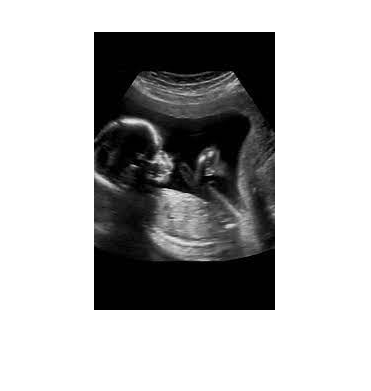

img=imread("bebe.jpg");
img=rgb2gray(img);
imshow(img)

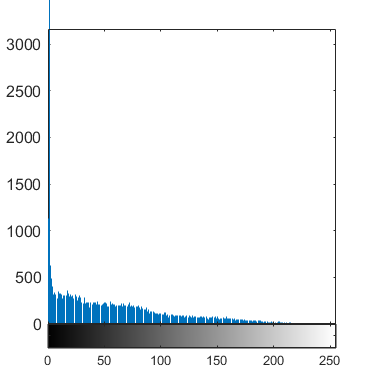

imhist(img)

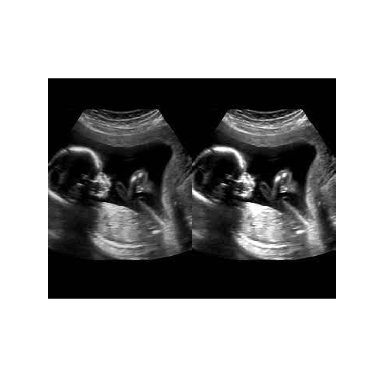

img1=imadjust(img);

montage({img,img1})

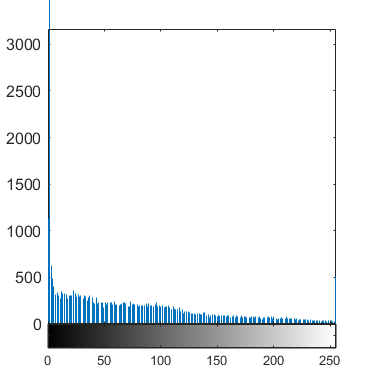

imhist(img1)

## Gamma Correction

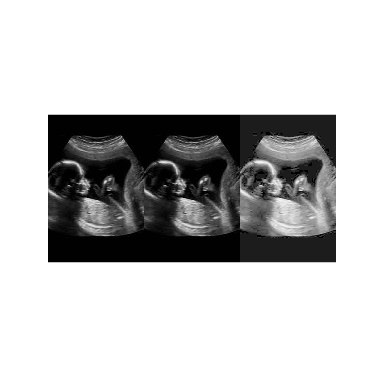

img2=imadjust(img,[],[],0.4);
montage({img,img,img2},"size",[1 3])

## Histogram Equalization

img3=histeq(img);
img3_1=adapthisteq(img);

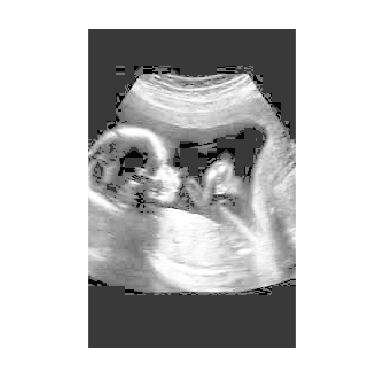

imshow(img3)

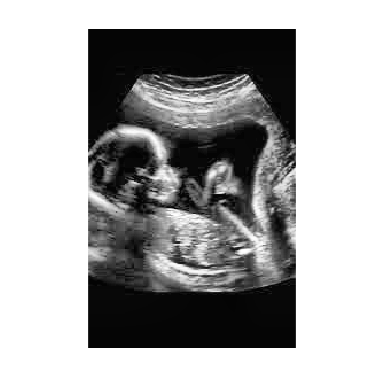

imshow(img3_1)

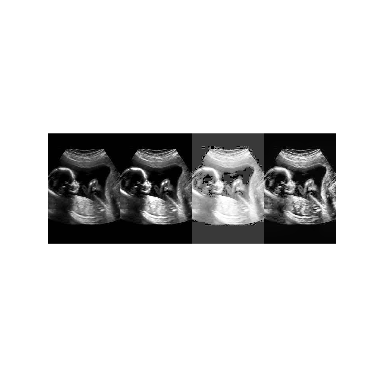


montage({img,img1,img3,img3_1},"size",[1 4])

## BRIGHTENING

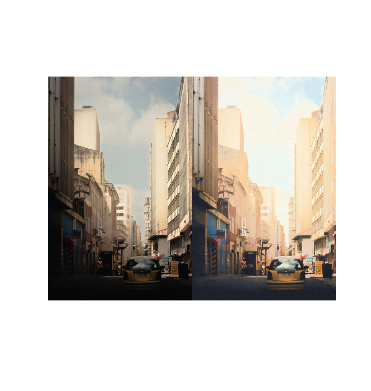

imgg=imread("des3.jpg");
img4=imlocalbrighten(imgg,0.5);

montage({imgg,img4})

## SHARPENING

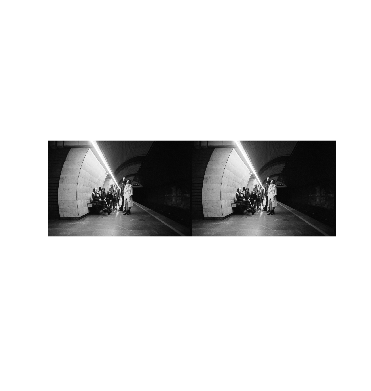

Img=imread("des1.jpg");
Img=rgb2gray(Img);

img5=imsharpen(Img,"Radius",1,"Amount",1);

montage({Img,img5})

## REDUCING HAZE

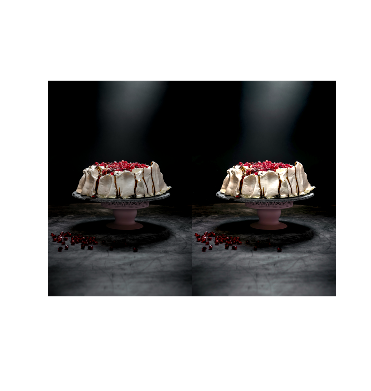

Imgg=imread("des2.jpg");
img6=imreducehaze(Imgg);
montage({Imgg,img6})